clear all; close all;
load('Entire_region.mat')


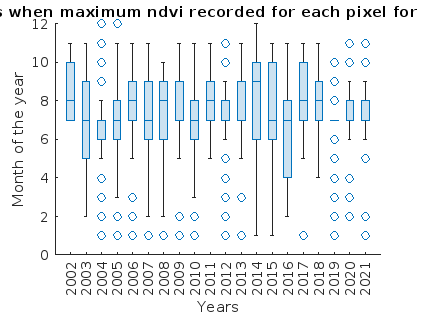

boxchart(month_maxndvi(2:end,:))
set(gca,'XTickLabel',{'2002','2003','2004','2005', ...
    '2006','2007','2008','2009','2010','2011','2012','2013', ...
    '2014','2015','2016','2017', '2018','2019','2020','2021'});

ylabel('Month of the year', 'FontName', 'Dialog'); 
xlabel('Years', 'FontName', 'Dialog');
title('Months when maximum ndvi recorded for each pixel for 20 years', 'FontName', 'Dialog');
saveas(gcf,'Published_Plots\Figure_9.a.pdf')

There are many pixels having maximum in january, lets find out what are there points

I will make 20 plots for 20 years, each map having pixels colored by month

month_maxndvi = month_maxndvi(2:end,:);
RGB = [247,252,245
229,245,224
199,233,192
161,217,155
116,196,118
65,171,93
35,139,69
0,109,44
0,68,27];

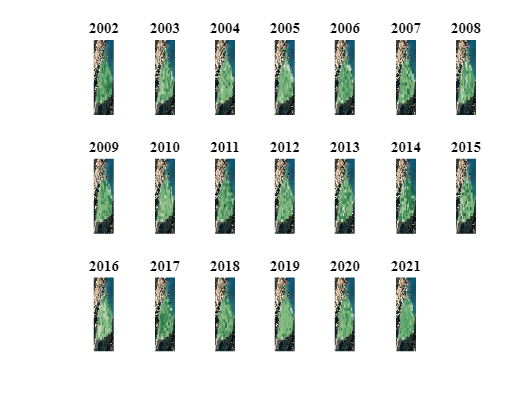

fig=figure(1);

for y = 1:20

    sp = subplot(3,7,y, 'Parent',fig);
    img=imread('Yukon_delta.jpg'); 
    image([ -138.447718 -138.570218],[61.033109 60.980258], img);
    hold('on');  

    A = ~isnan(ndvi(:,:, 15));
    Z_month = []; % nrXnc matrix
    x = 0;
    
    for j = 1:nc
        z_month_col = [];
        indx = find(A(:,j)>0);
        start_indx = indx(1);
        end_indx = indx(end);
        z_month_col(1:start_indx-1) = NaN;
        z_month_col(indx)=month_maxndvi(x+1: x+length(indx), y);
        z_month_col(end_indx+1:nr) = missing;
        x = x+length(indx);
        Z_month = [Z_month z_month_col'];
    end
    clear A; clear end_indx; clear start_indx; clear i; 
    clear x; clear z_month_col; clear indx


    [nr,nc]=size(Z_month);
    s= pcolor([X(:,1);nan],[Y(1,:), nan],[Z_month nan(nr,1); nan(1,nc+1)]' );
    s.EdgeColor = 'none' ;
    s.FaceAlpha = 0.7;
    
    c = colorbar; 
    caxis(sp, [1 12]);
    colormap(RGB./255);
    
    formatSpec = '%d';
    A1 = 2001+y;
    str = sprintf(formatSpec,A1);   
    title(str, 'FontName', 'Dialog')
    
    
    set(gca, 'xDir', 'reverse') 
    set(gca,'XAxisLocation','top','YAxisLocation','right','ydir','reverse');
    camroll(180)
    
    axis off
    colorbar off

    hold off;
    clear c; clear s; clear t; clear Z_month;


    clear b; clear y; clear img; clear j; clear formatSpec; 
    clear str; clear A1;
end

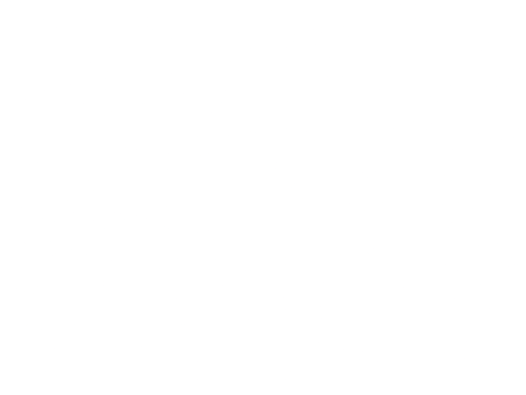

h = axes(fig,'visible','off'); 
h.Title.Visible = 'off';
h.XLabel.Visible = 'on';
h.YLabel.Visible = 'on';

c = colorbar(h,'Position',[0.93 0.168 0.022 0.7]);  % attach colorbar to h
colormap(RGB./255);
c.Label.String = 'Months (1-12)';
caxis(h,[1,12]); 
saveas(gcf,'Published_Plots\Figure_9.b.pdf')      

%writematrix([lats_all lons_all],'M.csv')